% Code originally based out of Josh the Engineer's tutorials
% Found here: https://github.com/jte0419/Panel_Methods
% Specifically, the SPVP Method

clear;
clc;

% Freestream velocity
Vinf = 1;

% Angle of Attack (deg)
AoA  = 5;

afName  = 'NACA0012';
airfoil = readmatrix([afName, '.csv']);

% Boundary point coordinates
XB = flipud(airfoil(:, 1));
YB = flipud(airfoil(:, 2));


% Number of boundary points
numPts = length(XB);

% Number of panels (control points)
numPan = numPts - 1;


%% PANEL METHOD GEOMETRY

% Initialize variables

% control point coordinates
XC = zeros(numPan,1);
YC = zeros(numPan,1);

% panel length array
S = zeros(numPan,1);

% panel orientation angle array [deg]
phiD = zeros(numPan,1);

% Find geometric quantities of the airfoil
for i = 1:1:numPan
    % X and Y values of control point
    XC(i) = 0.5*(XB(i)+XB(i+1));
    YC(i) = 0.5*(YB(i)+YB(i+1));

    % Change in X and Y between boundary points
    dx = XB(i+1)-XB(i);
    dy = YB(i+1)-YB(i);

    % Length of the panel
    S(i) = (dx^2 + dy^2)^0.5;

    % Angle of the panel (positive X-axis to inside face) [deg]
    phiD(i) = atan2d(dy,dx);

    % Make all panel angles positive [deg]
    if (phiD(i) < 0)
        phiD(i) = phiD(i) + 360;
    end
    
end

% Compute angle of panel normal w.r.t horizontal and include AoA
% Angle from positive X-axis to outward normal vector [deg]
deltaD = phiD + 90;
% Angle between freestream vector and outward normal vector [deg]
betaD = deltaD - AoA;
% Make all panel angles between 0 and 360 [deg]
betaD(betaD > 360) = betaD(betaD > 360) - 360;


% Convert angles from [deg] to [rad]
phi = deg2rad(phiD);
beta = deg2rad(betaD);


%% COMPUTE SOURCE AND VORTEX PANEL STRENGTHS

% Geometric integrals for SPM and VPM
% Normal
[I,J] = COMPUTE_IJ_SPM(XC,YC,XB,YB,phi,S);
% Tangential
[K,L] = COMPUTE_KL_VPM(XC,YC,XB,YB,phi,S);

% Populate A matrix
A = I + pi*eye(numPan,numPan);

% Right column of A matrix
% Loop over all i panels (rows)
for i = 1:1:numPan
    % Add gamma term to right-most column of A matrix
    A(i,numPan+1) = -sum(K(i,:));
end

% Bottom row of A matrix (Kutta condition)
% Loop over all j panels (columns)
for j = 1:1:numPan
    % Source contribution of Kutta condition equation
    A(numPan+1,j) = (J(1,j) + J(numPan,j));
end

% Vortex contribution of Kutta condition equation
A(numPan+1,numPan+1) = -sum(L(1,:) + L(numPan,:)) + 2*pi;

% Populate b array
b = -Vinf*2*pi*cos(beta);

% Last element of b array (Kutta condition)
% RHS of Kutta condition equation
b(numPan+1) = -Vinf*2*pi*(sin(beta(1)) + sin(beta(numPan)));

% Compute result array
% Solve system of equations for all source strengths and single vortex strength
resArr = A\b;

% Separate lambda and gamma values from result array
% All panel source strenths
lambda = resArr(1:end-1);
% Constant vortex strength
gamma  = resArr(end);


%% COMPUTE PANEL VELOCITIES AND PRESSURE COEFFICIENTS

% Compute velocities on each panel
% Initialize tangential velocity
Vt = zeros(numPan,1);
% Initialize pressure coefficient
Cp = zeros(numPan,1);

for i = 1:1:numPan
    % Uniform flow term
    term1 = Vinf*sin(beta(i));
    % Source panel terms when j is not equal to i
    term2 = (1/(2*pi))*sum(lambda.*J(i,:)');
    % Vortex panel term when j is equal to i
    term3 = gamma/2;
    % Vortex panel terms when j is not equal to i
    term4 = -(gamma/(2*pi))*sum(L(i,:));
    
    % Compute tangential velocity on panel i
    Vt(i) = term1 + term2 + term3 + term4;
    % Compute pressure coefficient on panel i
    Cp(i) = 1-(Vt(i)/Vinf)^2;
end

%% COMPUTE LIFT AND MOMENT

% Compute normal and axial force coefficients
CN = -Cp.*S.*sin(beta);
CA = -Cp.*S.*cos(beta);

% Compute lift and moment coefficients
CL = sum(CN.*cosd(AoA)) - sum(CA.*sind(AoA));
CM = sum(Cp.*(XC-0.25).*S.*cos(phi));

fprintf('Lift Coefficient (CL)\n');

Lift Coefficient (CL)


% From this SPVP code
fprintf('\tCode : %2.4f\n',CL);

	Code : 0.5824


% From Kutta-Joukowski lift equation
fprintf('\tK-J  : %g\n',2*sum(gamma.*S));                                   

	K-J  : 0.588842


fprintf('Moment Coefficient (CM)\n');

Moment Coefficient (CM)


% From this SPVP code
fprintf('\tSPVP : %2.4f\n',CM);

	SPVP : -0.0018




%% COMPUTE STREAMLINES

% Grid parameters

% X and Y grid for streamlines and contours
nGridX = 100;
nGridY = 100;

% X and Y-grid extents [min, max]
xVals = [min(XB)-0.5 max(XB)+0.5];
yVals = [min(YB)-0.3 max(YB)+0.3];

% Streamline parameters

% Step size for streamline propagation
stepsize = 0.01;
% Maximum vertices
maxVert = nGridX*nGridY*100;
% Percentage of streamlines of the grid
slPct = 25;
% Create array of Y streamline starting points
Ysl = linspace(yVals(1),yVals(2),floor((slPct/100)*nGridY))';

% Generate the grid points

% X and Y-values in evenly spaced grid
Xgrid = linspace(xVals(1),xVals(2),nGridX)';
Ygrid = linspace(yVals(1),yVals(2),nGridY)';
% Create meshgrid from X and Y grid arrays
[XX,YY] = meshgrid(Xgrid,Ygrid);


% Initialize X and Y velocity matrices
Vx = zeros(nGridX,nGridY);
Vy = zeros(nGridX,nGridY);

% Solve for grid point X and Y velocities
for m = 1:1:nGridX
    for n = 1:1:nGridY
        % Current iteration's X grid point
        XP = XX(m,n);
        % Current iteration's Y grid point
        YP = YY(m,n);
        
        % Compute Mx and My geometric integrals
        [Mx,My] = STREAMLINE_SPM(XP,YP,XB,YB,phi,S);
        % Compute Nx and Ny geometric integrals
        [Nx,Ny] = STREAMLINE_VPM(XP,YP,XB,YB,phi,S);
        
        [in,on] = inpolygon(XP,YP,XB,YB);

        % If the grid point is in or on the airfoil
        if (in == 1 || on == 1)
            % Set X and Y-velocities equal to zero
            Vx(m,n) = 0;
            Vy(m,n) = 0;
        % If the grid point is outside the airfoil
        else
            % Compute X and Y-velocities
            Vx(m,n) = Vinf*cosd(AoA) + sum(lambda.*Mx./(2*pi)) + sum(-gamma.*Nx./(2*pi));
            Vy(m,n) = Vinf*sind(AoA) + sum(lambda.*My./(2*pi)) + sum(-gamma.*Ny./(2*pi));
        end
    end
end

% Compute grid point magnitude of velocity vector []
Vxy  = sqrt(Vx.^2 + Vy.^2);
% Compute grid point Pressure coefficient []
CpXY = 1-(Vxy./Vinf).^2;


%% CIRCULATION AND SOURCE/VORTEX STRENGTH CHECKS

% Compute circulation
% Ellipse horizontal half-length
aa   = 0.75;
% Ellipse vertical half-length
bb   = 0.25;
% Ellipse center X-coordinate
x0   = 0.5;
% Ellipse center Y-coordinate
y0   = 0;
% Number of points on ellipse
numT = 5000;
% Compute circulation around ellipse
[Circulation,xC,yC,VxC,VyC] = COMPUTE_CIRCULATION(aa,bb,x0,y0,numT,Vx,Vy,XX,YY);

% Check the sum of the source strenghts
fprintf('======= CIRCULATION RESULTS =======\n');

======= CIRCULATION RESULTS =======


% Sum of source strengths ([L]ambda)
fprintf('Sum of L     : %3.7f\n',sum(lambda.*S));

Sum of L     : 0.0058807


% Sum of vortex strengths ([G]amma)
fprintf('Sum of G     : %3.7f\n',sum(gamma.*S));

Sum of G     : 0.2944210


% Circulation
fprintf('Circulation  : %3.7f\n',Circulation);

Circulation  : 0.2944352


% Lift coefficient from K-J equation
fprintf('K-J from G   : %3.7f\n',2*sum(gamma.*S));

K-J from G   : 0.5888421


% Lift coefficient from K-J equation
fprintf('K-J from Circ: %3.7f\n',2*Circulation);

K-J from Circ: 0.5888705


fprintf('===================================\n');

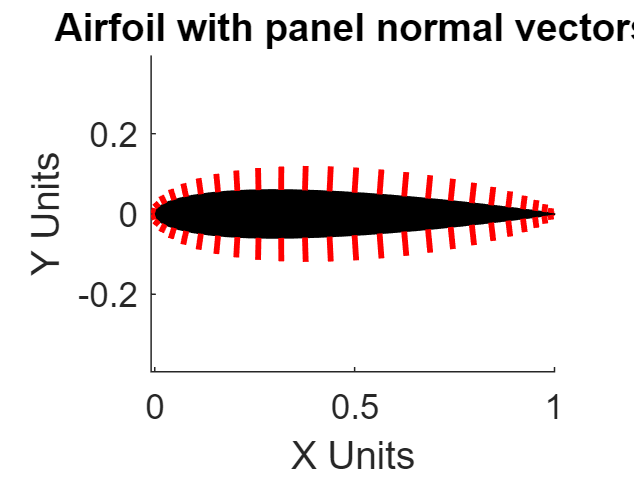


%% PLOTTING

% FIGURE: Airfoil with panel normal vectors
figure(1);
cla; hold on; grid off;
title('Airfoil with panel normal vectors')
set(gcf,'Color','White');
set(gca,'FontSize',12);

% Plot airfoil
fill(XB,YB,'k');

% Loop over all panels
for i = 1:1:numPan
    % Set X start of panel orientation vector
    X(1) = XC(i);
    % Set X end of panel orientation vector
    X(2) = XC(i) + S(i)*cosd(betaD(i)+AoA);
    % Set Y start of panel orientation vector
    Y(1) = YC(i);
    % Set Y end of panel orientation vector
    Y(2) = YC(i) + S(i)*sind(betaD(i)+AoA);
    % Plot panel normal vector
    plot(X,Y,'r-','LineWidth',2);
end

xlabel('X Units');
ylabel('Y Units');
xlim('auto');
ylim('auto');
axis equal;
zoom reset;

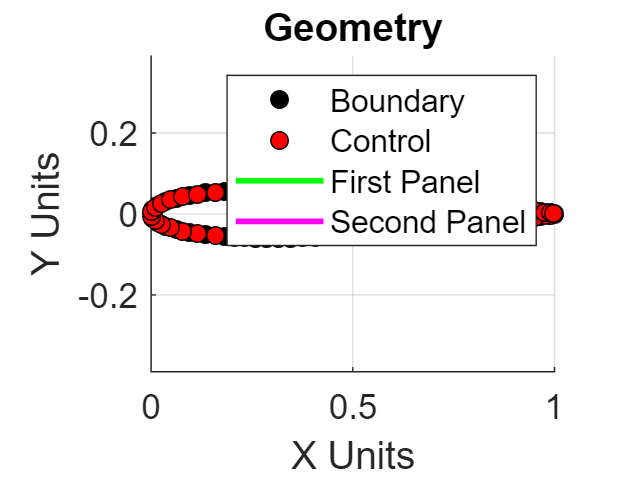


% FIGURE: Geometry with the following indicated:
% - Boundary pts, control pts, first panel, second panel
figure(2);
cla; hold on; grid on;
title('Geometry')
set(gcf,'Color','White');
set(gca,'FontSize',12);

% Plot airfoil panels
plot(XB,YB,'k-','LineWidth',3);
% Plot first panel
p1 = plot([XB(1) XB(2)],[YB(1) YB(2)],'g-','LineWidth',2);
% Plot second panel
p2 = plot([XB(2) XB(3)],[YB(2) YB(3)],'m-','LineWidth',2);
% Plot boundary points (black circles)
pB = plot(XB,YB,'ko','MarkerFaceColor','k');
% Plot control points (red circles)
pC = plot(XC,YC,'ko','MarkerFaceColor','r');

legend([pB,pC,p1,p2],{'Boundary','Control','First Panel','Second Panel'});

xlabel('X Units');
ylabel('Y Units');
xlim('auto');
ylim('auto');
axis equal;
zoom reset;

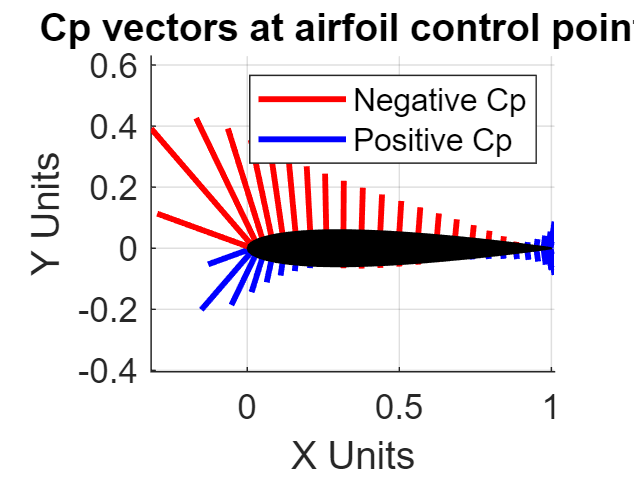


% FIGURE: Cp vectors at airfoil control points
figure(3);
cla; hold on; grid on;
title('Cp vectors at airfoil control points')
set(gcf,'Color','White');
set(gca,'FontSize',12);
% Scale and make positive all Cp values
Cps = abs(Cp*0.25);
% Loop over all panels
for i = 1:1:length(Cps)
    % Control point X-coordinate
    X(1) = XC(i);
    % Ending X-value based on Cp magnitude
    X(2) = XC(i) + Cps(i)*cosd(betaD(i)+AoA);
    % Control point Y-coordinate
    Y(1) = YC(i);
    % Ending Y-value based on Cp magnitude
    Y(2) = YC(i) + Cps(i)*sind(betaD(i)+AoA);
    
    % If pressure coefficient is negative
    if (Cp(i) < 0)
        % Plot as a red line
        p{1} = plot(X,Y,'r-','LineWidth',2);
    % If pressure coefficient is zero or positive
    elseif (Cp(i) >= 0)
        % Plot as a blue line
        p{2} = plot(X,Y,'b-','LineWidth',2);
    end
end

% Plot the airfoil as black polygon
fill(XB,YB,'k');

legend([p{1},p{2}],{'Negative Cp','Positive Cp'});
xlabel('X Units');
ylabel('Y Units');
xlim('auto');
ylim('auto');
axis equal;
zoom reset;

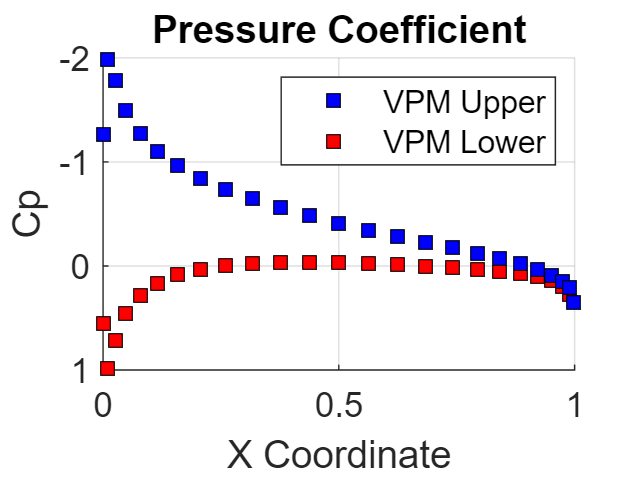



% FIGURE: Pressure coefficient
figure(4);
cla; hold on; grid on;
title('Pressure Coefficient')
set(gcf,'Color','White');
set(gca,'FontSize',12);

% Airfoil middle index for SPM data
midIndS = floor(length(Cp)/2);
% Plot Cp for upper surface of airfoil from SPM
pVl = plot(XC(1:midIndS),Cp(1:midIndS),'ks','MarkerFaceColor','r');
% Plot Cp for lower surface of airfoil from SPM
pVu = plot(XC(midIndS+1:end),Cp(midIndS+1:end),'ks','MarkerFaceColor','b');

legend([pVu,pVl],{'VPM Upper','VPM Lower'});
xlabel('X Coordinate');
ylabel('Cp');
xlim([0 1]);
ylim('auto');
set(gca,'Ydir','reverse')
zoom reset;

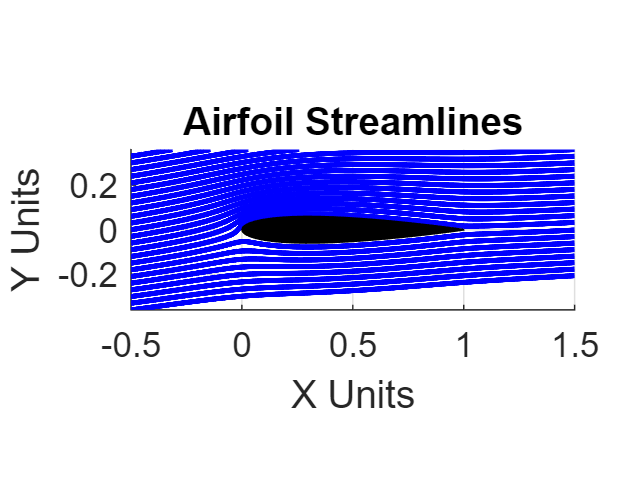


% FIGURE: Airfoil streamlines
figure(5);
cla; hold on; grid on;
title('Airfoil Streamlines')
set(gcf,'Color','White');
set(gca,'FontSize',12);

% Loop over all Y streamline starting points
for i = 1:1:length(Ysl)
    % Plot the streamline
    sl = streamline(XX,YY,Vx,Vy,xVals(1),Ysl(i),[stepsize,maxVert]);
    % Set streamline line width
    set(sl,'LineWidth',2);
end

% Plot airfoil as black polygon
fill(XB,YB,'k');

xlabel('X Units');
ylabel('Y Units');
xlim(xVals);
axis equal;
ylim(yVals);
zoom reset;

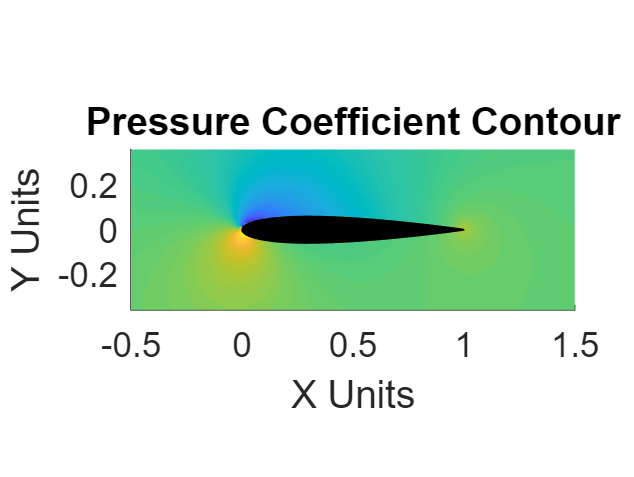


% FIGURE: Pressure coefficient contour
figure(6);
cla; hold on; grid on;
title('Pressure Coefficient Contour')
set(gcf,'Color','White');
set(gca,'FontSize',12);

% Plot Cp contour
contourf(XX,YY,CpXY,100,'EdgeColor','none');

% Plot airfoil as black polygon
fill(XB,YB,'k');

xlabel('X Units');
ylabel('Y Units');
xlim(xVals);
axis equal;
ylim(yVals);
zoom reset;

function [Nx,Ny] = STREAMLINE_VPM(XP,YP,XB,YB,phi,S)

% FUNCTION - COMPUTE Nx AND Ny GEOMETRIC INTEGRALS FOR VORTEX PANEL METHOD
% PURPOSE
% - Compute the integral expression for constant strength vortex panels
% - Vortex panel strengths are constant, but can change from panel to panel
% - Geometric integral for X-velocity: Nx(pj)
% - Geometric integral for Y-velocity: Ny(pj)
% 
% INPUTS
% - XP     : X-coordinate of computation point, P
% - YP     : Y-coordinate of computation point, P
% - XB     : X-coordinate of boundary points
% - YB     : Y-coordinate of boundary points
% - phi    : Angle between positive X-axis and interior of panel
% - S      : Length of panel
% 
% OUTPUTS
% - Nx     : Value of X-direction geometric integral
% - Ny     : Value of Y-direction geometric integral
    
    % Number of panels (control points)
    numPan = length(XB)-1;
    
    % Initialize Nx and Ny integral arrays
    Nx = zeros(numPan,1);
    Ny = zeros(numPan,1);
    
    % Compute Nx and Ny
    % Loop over all panels
    for j = 1:1:numPan
        % Compute intermediate values

        A  = -(XP-XB(j))*cos(phi(j))-(YP-YB(j))*sin(phi(j));
        B  = (XP-XB(j))^2+(YP-YB(j))^2;
        
        % C and D terms (X-direction)
        Cx = sin(phi(j));                                                       
        Dx = -(YP-YB(j));                                                       
        % C and D terms (Y-direction)
        Cy = -cos(phi(j));
        Dy = XP-XB(j);

        E  = sqrt(B-A^2);
        if (~isreal(E))
            E = 0;
        end
        
        % Compute Nx
        % First term in Nx equation
        term1 = 0.5*Cx*log((S(j)^2+2*A*S(j)+B)/B);
        % Second term in Nx equation
        term2 = ((Dx-A*Cx)/E)*(atan2((S(j)+A),E) - atan2(A,E));
        % Compute Nx integral
        Nx(j) = term1 + term2;
        
        % Compute Ny
        % First term in Ny equation
        term1 = 0.5*Cy*log((S(j)^2+2*A*S(j)+B)/B);
        % Second term in Ny equation
        term2 = ((Dy-A*Cy)/E)*(atan2((S(j)+A),E) - atan2(A,E));
        % Compute Ny integral
        Ny(j) = term1 + term2;
        
	    % Zero out any NANs, INFs, or imaginary numbers
        if (isnan(Nx(j)) || isinf(Nx(j)) || ~isreal(Nx(j)))
            Nx(j) = 0;
        end
        if (isnan(Ny(j)) || isinf(Ny(j)) || ~isreal(Ny(j)))
            Ny(j) = 0;
        end
    end

end

function [Mx,My] = STREAMLINE_SPM(XP,YP,XB,YB,phi,S)

% FUNCTION - COMPUTE Mx AND My GEOMETRIC INTEGRALS FOR SOURCE PANEL METHOD
% PURPOSE
% - Compute the geometric integral at point P due to source panels
% - Source panel strengths are constant, but can change from panel to panel
% - Geometric integral for X-direction: Mx(pj)
% - Geometric integral for Y-direction: My(pj)
%
% INPUTS
% - XP     : X-coordinate of computation point, P
% - YP     : Y-coordinate of computation point, P
% - XB     : X-coordinate of boundary points
% - YB     : Y-coordinate of boundary points
% - phi    : Angle between positive X-axis and interior of panel
% - S      : Length of panel
% 
% OUTPUTS
% - Mx     : Value of X-direction geometric integral
% - My     : Value of Y-direction geometric integral
    
    % Number of panels/control points
    numPan = length(XB)-1;
    
    % Initialize Mx and My integral arrays
    Mx = zeros(numPan,1);
    My = zeros(numPan,1);
    
    % Compute Mx and My
    % Loop over the j panels
    for j = 1:1:numPan

        % Compute intermediate values

        A  = -(XP-XB(j))*cos(phi(j))-(YP-YB(j))*sin(phi(j));
        B  = (XP-XB(j))^2+(YP-YB(j))^2;

        % C and D in x-direction
        Cx = -cos(phi(j));
        Dx = XP - XB(j);
        
        % C and D in y-direction
        Cy = -sin(phi(j));
        Dy = YP - YB(j);
        
        E  = sqrt(B-A^2);
        if (~isreal(E))
            E = 0;
        end
        
        % Compute Mx
        % First term in Mx equation
        term1 = 0.5*Cx*log((S(j)^2+2*A*S(j)+B)/B);
        % Second term in Mx equation
        term2 = ((Dx-A*Cx)/E)*(atan2((S(j)+A),E) - atan2(A,E));
        % X-direction geometric integral
        Mx(j) = term1 + term2;
        
        % Compute My
        % First term in My equation
        term1 = 0.5*Cy*log((S(j)^2+2*A*S(j)+B)/B);
        % Second term in My equation
        term2 = ((Dy-A*Cy)/E)*(atan2((S(j)+A),E) - atan2(A,E));
        % Y-direction geometric integral
        My(j) = term1 + term2;
        
        % Zero out any NANs, INFs, or imaginary numbers
        if (isnan(Mx(j)) || isinf(Mx(j)) || ~isreal(Mx(j)))
            Mx(j) = 0;
        end
        if (isnan(My(j)) || isinf(My(j)) || ~isreal(My(j)))
            My(j) = 0;
        end
    end

end



function [K,L] = COMPUTE_KL_VPM(XC,YC,XB,YB,phi,S)

% FUNCTION - COMPUTE K AND L GEOMETRIC INTEGRALS FOR VORTEX PANEL METHOD
% PURPOSE
% - Compute the integral expression for constant strength vortex panels
% - Vortex panel strengths are constant, but can change from panel to panel
% - Geometric integral for panel-normal    : K(ij)
% - Geometric integral for panel-tangential: L(ij)
%
% INPUTS
% - XC  : X-coordinate of control points
% - YC  : Y-coordinate of control points
% - XB  : X-coordinate of boundary points
% - YB  : Y-coordinate of boundary points
% - phi : Angle between positive X-axis and interior of panel
% - S   : Length of panel
% 
% OUTPUTS
% - K   : Value of panel-normal integral
% - L   : Value of panel-tangential integral

    % Number of panels
    numPan = length(XC);
    
    % Initialize K and L Integral Matrices
    K = zeros(numPan,numPan);
    L = zeros(numPan,numPan);
    
    % Compute integral
    % Loop over i panels
    for i = 1:1:numPan
        % Loop over j panels
        for j = 1:1:numPan
            if (j ~= i)% If panel j is not the same as panel i
                A  = -(XC(i)-XB(j))*cos(phi(j))-(YC(i)-YB(j))*sin(phi(j));
                B  = (XC(i)-XB(j))^2+(YC(i)-YB(j))^2;

                % C and D normal
                Cn = -cos(phi(i)-phi(j));
                Dn = (XC(i)-XB(j))*cos(phi(i))+(YC(i)-YB(j))*sin(phi(i));
                
                % C and D tangential
                Ct = sin(phi(j)-phi(i));
                Dt = (XC(i)-XB(j))*sin(phi(i))-(YC(i)-YB(j))*cos(phi(i));

                E  = sqrt(B-A^2);
                if (~isreal(E))
                    E = 0;
                end
                
                % Compute K
                % First term in K equation
                term1  = 0.5*Cn*log((S(j)^2+2*A*S(j)+B)/B);
                % Second term in K equation
                term2  = ((Dn-A*Cn)/E)*(atan2((S(j)+A),E)-atan2(A,E));
                % Compute K integral
                K(i,j) = term1 + term2;
                
                % Compute L
                % First term in L equation
                term1  = 0.5*Ct*log((S(j)^2+2*A*S(j)+B)/B);
                % Second term in L equation
                term2  = ((Dt-A*Ct)/E)*(atan2((S(j)+A),E)-atan2(A,E));
                % Compute L integral
                L(i,j) = term1 + term2;
            end
            
            % Zero out any NANs, INFs, or imaginary numbers
            if (isnan(K(i,j)) || isinf(K(i,j)) || ~isreal(K(i,j)))
                K(i,j) = 0;
            end
            if (isnan(L(i,j)) || isinf(L(i,j)) || ~isreal(L(i,j)))
                L(i,j) = 0;
            end
        end
    end

end



function [I,J] = COMPUTE_IJ_SPM(XC,YC,XB,YB,phi,S)
% PURPOSE
% - Compute the integral expression for constant strength source panels
% - Source panel strengths are constant, but can change from panel to panel
% - Geometric integral for panel-normal    : I(ij)
% - Geometric integral for panel-tangential: J(ij)
%
% INPUTS
% - XC  : X-coordinate of control points
% - YC  : Y-coordinate of control points
% - XB  : X-coordinate of boundary points
% - YB  : Y-coordinate of boundary points
% - phi : Angle between positive X-axis and interior of panel
% - S   : Length of panel
% 
% OUTPUTS
% - I   : Value of panel-normal integral (Eq. 3.163 in Anderson)
% - J   : Value of panel-tangential integral (Eq. 3.165 in Anderson)

    % Number of panels/control points
    numPan = length(XC);
    
    % Initialize I and J Integral Matrices
    I = zeros(numPan,numPan);
    J = zeros(numPan,numPan);
    
    % Compute integral
    % Loop over i panels
    for i = 1:1:numPan
        % Loop over j panels
        for j = 1:1:numPan
            % If the i and j panels are not the same
            if (j ~= i)
                % Compute intermediate values

                A  = -(XC(i)-XB(j))*cos(phi(j))-(YC(i)-YB(j))*sin(phi(j));
                B  = (XC(i)-XB(j))^2+(YC(i)-YB(j))^2;
                
                % C and D normal
                Cn = sin(phi(i)-phi(j));
                Dn = -(XC(i)-XB(j))*sin(phi(i))+(YC(i)-YB(j))*cos(phi(i));
                
                % C and D tangential
                Ct = -cos(phi(i)-phi(j));
                Dt = (XC(i)-XB(j))*cos(phi(i))+(YC(i)-YB(j))*sin(phi(i));

                E  = sqrt(B-A^2);
                if (~isreal(E))
                    E = 0;
                end
                
                % Compute I (needed for normal velocity)
                % First term in I equation
                term1  = 0.5*Cn*log((S(j)^2+2*A*S(j)+B)/B);
                % Second term in I equation
                term2  = ((Dn-A*Cn)/E)*(atan2((S(j)+A),E) - atan2(A,E));
                % Compute I integral
                I(i,j) = term1 + term2;
                
                % Compute J (needed for tangential velocity)
                % First term in J equation
                term1  = 0.5*Ct*log((S(j)^2+2*A*S(j)+B)/B);
                % Second term in J equation
                term2  = ((Dt-A*Ct)/E)*(atan2((S(j)+A),E) - atan2(A,E));
                % Compute J integral
                J(i,j) = term1 + term2;
            end
            
            % Zero out any NANs, INFs, or imaginary numbers
            if (isnan(I(i,j)) || isinf(I(i,j)) || ~isreal(I(i,j)))
                I(i,j) = 0;
            end
            if (isnan(J(i,j)) || isinf(J(i,j)) || ~isreal(J(i,j)))
                J(i,j) = 0;
            end
        end
    end

end


% PURPOSE
% - Compute the circulation around the defined ellipse
% 
% INPUTS
% - a    : Horizontal axis half-length
% - b    : Vertical axis half-length
% - x0   : Ellipse center X coordinate
% - y0   : Ellipse center Y coordinate
% - numT : Number of points for integral
% - XX   : Meshgrid X values
% - YY   : Meshgrid Y values
%
% OUTPUTS
% - Lambda : Circulation [length^2/time]
% - xC     : X-values of integral curve [numT x 1]
% - yC     : Y-values of integral curve [numT x 1]
% - VxC    : Velocity X-component on integral curve [numT x 1]
% - VyC    : Velocity Y-component on integral curve [numT x 1]

function [Gamma,xC,yC,VxC,VyC] = COMPUTE_CIRCULATION(a,b,x0,y0,numT,Vx,Vy,XX,YY)

    % Ending angle [rad]
    tEnd  = (2*pi) - ((2*pi)/numT);
    % Discretize ellipse into angles [rad]
    t     = linspace(0,tEnd,numT)';
    % X coordinates of ellipse
    xC    = a*cos(t) + x0;
    % Y coordinates of ellipse
    yC    = b*sin(t) + y0;
    % X velocity component on ellipse
    VxC   = interp2(XX,YY,Vx,xC,yC);
    % Y velocity component on ellipse
    VyC   = interp2(XX,YY,Vy,xC,yC);
    % Compute integral using trapezoid rule
    Gamma = -(trapz(xC,VxC) + trapz(yC,VyC));


end